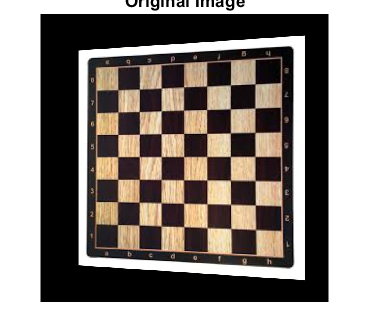

clc;
clear;
% close all;
tic
%% Input Image
[file,path] = uigetfile('*.*');
f1 = fullfile(path,file);
if prod(double(file) == 0) && prod(double(path) == 0)
    return
end   
a = imread(f1);


%% Input Formating
in = input('Press 1 for Rotate and 2 for Transform : ');
if in==1
    angle = input('Enter angle in Degrees : ');
    in1 = input('Press 1 for further transform else 2 : ');
    if in1 == 1
        homo = input('3D rotation as row vector (1x3) : ');
        anglerad = pi*angle/180;
        A1 = [cos(anglerad), sin(anglerad);-sin(anglerad),cos(anglerad)];
        A = [A1,[0;0];homo];
    else
        anglerad = pi*angle/180;
        A = [cos(anglerad), sin(anglerad),0;-sin(anglerad),cos(anglerad),0;0,0,1];
    end
else 
    A = input('Enter transform Matrix : ');
end
a1=0;

% Is it color or grayscale
b = size(a);
if size(b,2)==3
a1 = 1;
end

%Convert to double
a= double(a);                       

%% Transform 

% Bring the origin to the center by this Matrix
trans = [1,0,-b(2)/2;0,1,-b(1)/2;0,0,1];

%Transform Happens Here

outx = zeros(b(1),b(2));
outy = zeros(b(1),b(2));

for i = 1:b(1)
    for j = 1:b(2)
        new  = A*trans*[j;i;1];
        outx(i,j) = round(new(1)/new(3));
        outy(i,j) = round(new(2)/new(3));
    end
end
%% Forming the transformed image
minoutx = min(outx,[],'all');
minouty = min(outy,[],'all');

maxoutx = max(outx,[],'all');
maxouty = max(outy,[],'all');

f = zeros(maxouty+abs(minouty)+1,maxoutx+abs(minoutx)+1);

for i = 1:b(1)
    for j = 1:b(2)
        f(outy(i,j)+abs(minouty)+1,outx(i,j)+abs(minoutx)+1,1) = a(i,j,1);
        if a1 == 1
            f(outy(i,j)+abs(minouty)+1,outx(i,j)+abs(minoutx)+1,2) = a(i,j,2);
            f(outy(i,j)+abs(minouty)+1,outx(i,j)+abs(minoutx)+1,3) = a(i,j,3);
        end
        
    end
end

%% Fill the gaps
%Fill in the gaps By using Median Filter
b1 = size(f);
for i = 2:b1(1)-2
    for j = 2:b1(2)-2
        if f(i,j)==0
       f(i,j) = median([f(i-1,j-1),f(i-1,j),f(i-1,j+1),f(i,j-1),f(i,j),f(i,j+1),f(i+1,j-1),f(i+1,j),f(i+1,j+1)]);
       if a1 == 1
       f(i,j,2) = median([f(i-1,j-1,2),f(i-1,j,2),f(i-1,j+1,2),f(i,j-1,2),f(i,j,2),f(i,j+1,2),f(i+1,j-1,2),f(i+1,j,2),f(i+1,j+1,2)]);
       f(i,j,3) = median([f(i-1,j-1,3),f(i-1,j,3),f(i-1,j+1,3),f(i,j-1,3),f(i,j,3),f(i,j+1,3),f(i+1,j-1,3),f(i+1,j,3),f(i+1,j+1,3)]);
       end
        end
    end
end


%% Display the Images
figure;
imshow(uint8(a));
title('Original Image')

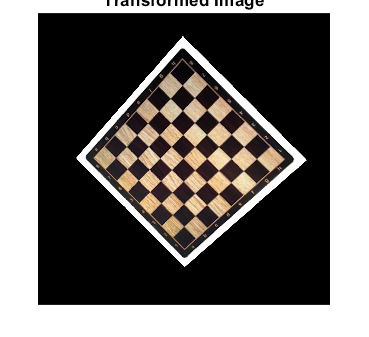

figure;
imshow(uint8(f));
title('Transformed Image')

toc

Elapsed time is 62.178184 seconds.



%% Save the image ?
in2 = input('Do you want to save the image ? (Press 1 for yes 2 for No) : ');
if in2 == 1
    [file,path] = uiputfile('*.*');
    f2 = fullfile(path,file);
    imwrite(uint8(f),f2);
end